%% Clean the memory and worksapace 
close all ;
clear     ;
clc       ;

#### **SYSTEM IDENTIFICATION USING META LEARNING**

%[traf_noise,fs] = audioread("audio/traffic_noise.wav");

T   =   5        ; % time-duration
t   =   0:1/fs:T  ;
N   =   length(t); % number of data points.

Len_filt = 512      ; % length of control filter.

load("path/P1.mat","P1")    ; %load primary path 
load path/S1.mat S1   ;  %secondary path
Pri = P1;
Track_num = 3         ; % number of the track for training 
Noise=randn(1:N) 

Noise =     0.0280
    0.0258
    0.0234
    0.0211
    0.0186
    0.0159
    0.0132
    0.0109
    0.0090
    0.0077


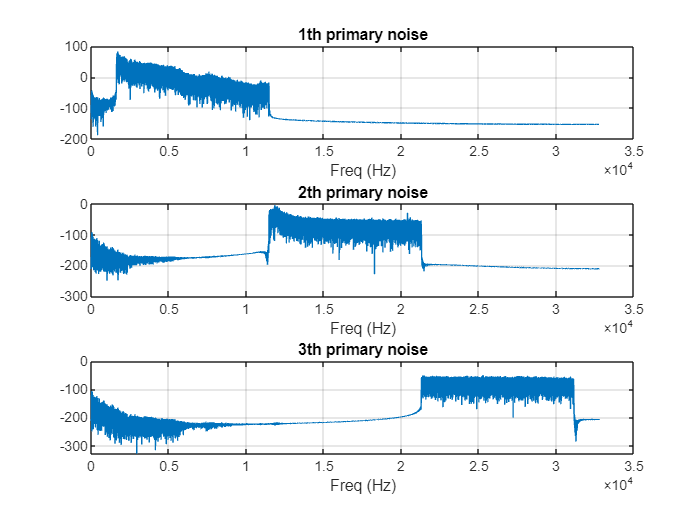



%frequency filter 
freq_filt1 = fir1(6000,[0.05 0.35]); %6000th order & 1 -> fs/2
freq_filt2 = fir1(6000,[0.35 0.65]) ;
freq_filt3 = fir1(6000,[0.65,0.95]) ;

% Primary noise 
Pri_noise1 = filter(freq_filt1,1,Noise) ;
Pri_noise2 = filter(freq_filt2,1,Noise) ;
Pri_noise3 = filter(freq_filt3,1,Noise) ;
% Drawing fiture 
data = [Pri_noise1,Pri_noise2,Pri_noise3];

len_f = length(Pri_noise1)   ;
len_hal = round(len_f/2);

for i = 1:3
    freq = 20*log(abs(fft(data(:,i))));
    subplot(3,1,i);
    plot(0:(fs/len_f):(len_hal-1)*(fs/len_f), freq(1:len_hal));
    grid on   ;
    title(num2str(i)+"th primary noise")
    xlabel('Freq (Hz)')
end

% Distrubance signal
Distur_1 = filter(Pri,1,Pri_noise1);
Distur_2 = filter(Pri,1,Pri_noise2);
Distur_3 = filter(Pri,1,Pri_noise3);

% reference signal 
reference_signal_1 = filter(S1,1,Pri_noise1);
reference_signal_2 = filter(S1,1,Pri_noise2);
reference_signal_3 = filter(S1,1,Pri_noise3);


Num_epcho  = 100000;                      % number of  epcho 
Trac     = randi(Track_num,[Num_epcho,1]) ; % Randomly choosing the different tracks. 
Len_data = length(Distur_1)               ;

len   = Len_filt  ;
ref_data = zeros(Len_filt,Num_epcho);

Di_data = zeros(Len_filt,Num_epcho);
Ref_data = [reference_signal_1,reference_signal_2,reference_signal_3]   ;
Dis_data = [Distur_1,Distur_2,Distur_3];
for j = 1:Num_epcho
    End = randi([len,Len_data]);
    Di_data(:,j) = Dis_data(End-511:End,Trac(j));
    ref_data(:,j) = Ref_data(End-511:End,Trac(j));
end
% save('data_set.mat','Di_data','ref_data');


### *M*`odified MAML Algorithm`

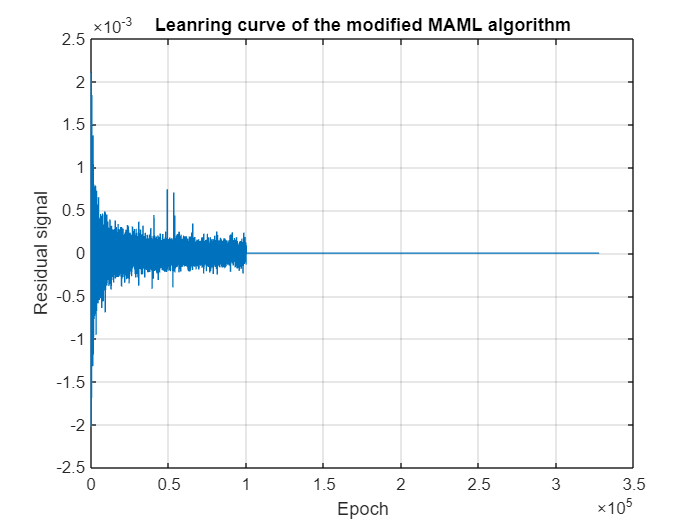

Wo = zeros(Len_filt,1) ;      
Er_zero = zeros(N,1)         ; % Residual signal
 
mu    = 5              ; %  step size

lamda = 0.995              ;% forget factor 
 
epslon = 2.3 ;          %   MAML learning rate 

% using MAML algorithm 
for j = 1:Num_epcho
    ref_data_new = flipud(ref_data(:,j));
    Di_data_new = flipud(Di_data(:,j));
    Grad = 0; % gradiant 
    Er   = 0; % Training error signal

    e = Di_data_new(1) - Wo'*ref_data_new;
    Wo   = Wo + mu*e*ref_data_new;

    for k = 1:Len_filt
        Fd = [ref_data_new(k:end);zeros(k-1,1)];
        e  = Di_data_new(k) - Wo'*Fd;
        Grad = Grad + epslon*(mu/Len_filt)*e*Fd*(lamda^(k-1));

        if k==1
            Er = e;
        end
    end
    Wo = Wo + Grad;
    Er_zero(j) = Er;
end

% Drawing the residual error of the Modified MAML algorihtm 
figure    ;
plot(Er_zero)  ;
grid on   ;
title('Leanring curve of the modified MAML algorithm');
xlabel('Epoch');
ylabel('Residual signal');

% Getting the optimal intial control filter
%Wo = a.Phi ;
save('init_weight.mat','Wo');

load("init_weight.mat","Wo")

filename1 = 'audio/1-100032-A-0.wav';
filename2 = 'audio/1-100038-A-14.wav';
filename3 = 'audio/1-100210-A-36.wav';
filename4 = 'audio/1-100210-B-36.wav';

[y1, ~] = audioread(filename1);
[y2, ~] = audioread(filename2);
[y3, ~] = audioread(filename3);
[y4, Fs] = audioread(filename4);

Y = [y1;y2;y3;y4];

audiowrite("results/disturbance.wav", Y, Fs);

load("path/P1.mat","P1")    ; %load primary path 
load path/S1.mat S1   ;  %secondary path
Pri = P1;
Len_filt = 512  ; 
Pri_noise1   =Y      ; 
% Generating the disturbacne 
Distur_1   = filter(Pri,1,Pri_noise1)            ;
           
reference_signal_1    = filter(S1,1,Pri_noise1)  ;% ref signal
Wc_initial = zeros(Len_filt,1);
muw        = 0.001 ; % Step size of All FxLMS algorithms. 
Er_zero         = FxLMS(Len_filt, Wc_initial, Distur_1, reference_signal_1, muw);

Wc_initial = Wo;% MAML weight intialization
Er_maml        = FxLMS(Len_filt, Wc_initial, Distur_1, reference_signal_1, muw);

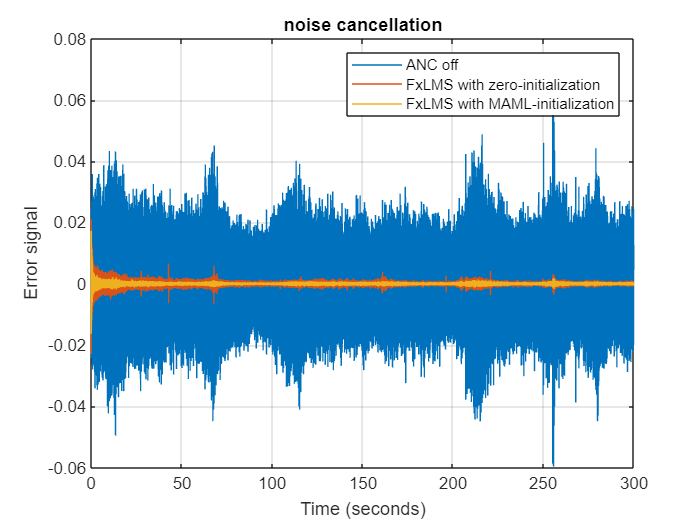

figure 
% Drawing the figures of the MAML and FxLMS 
plot((0:length(Distur_1)-1)*(1/Fs),Distur_1,(0:length(Er_zero)-1)*(1/Fs),Er_zero,(0:length(Er_maml)-1)*(1/Fs),Er_maml);
title('noise cancellation')
xlabel('Time (seconds)')
ylabel('Error signal')
legend({'ANC off','FxLMS with zero-initialization','FxLMS with MAML-initialization'})
grid on;

audiowrite("results/Error_MAML_init.wav", Er_maml, Fs);
audiowrite("results/Error_FxLMS_zero_init.wav", Er_zero, Fs);

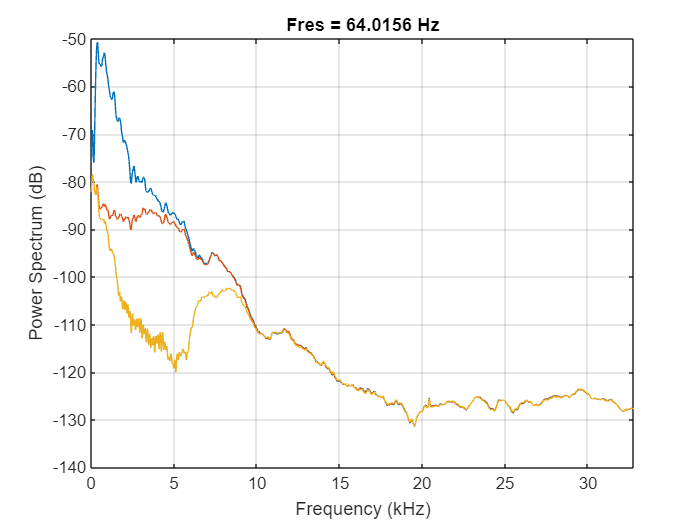

pspectrum(Distur_1,Fs)
hold on
pspectrum(Er_zero,Fs)
pspectrum(Er_maml,Fs)